% 题1
function verify_roots(p, r, tol)
    % p: 多项式的系数向量,r: roots 函数的输出
    % tol: 误差容限
    all_passed = true;
    for i = 1:length(r)
        if abs(polyval(p, r(i))) > tol
            fprintf('根 %f + %fi 可能不准确\n', real(r(i)), imag(r(i)));
            all_passed = false;
        end
    end
    if all_passed
        fprintf('所有的根都已经通过验证，求根正确。\n');
    end
end

% 1.1
tol = 1e-6; % 定义容差
p = [1 1 1];
r = roots(p)

r =          -0.5 +    0.86603i
         -0.5 -    0.86603i


verify_roots(p, r, tol)

所有的根都已经通过验证，求根正确。


% 1.2
p = [3 0 -4 0 2 -1];
r = roots(p)

r =       -0.9479 +    0.38447i
      -0.9479 -    0.38447i
            1 +          0i
       0.4479 +    0.34346i
       0.4479 -    0.34346i


verify_roots(p, r, tol)

所有的根都已经通过验证，求根正确。


% 1.3
p = zeros(1,24);
p([1 17 18 22]) = [5 -6 8 -5];
r = roots(p)

r =             0 +          0i
            0 +          0i
      0.97678 +          0i
      0.93877 +    0.26824i
      0.93877 -    0.26824i
      0.85538 +    0.53626i
      0.85538 -    0.53626i
      0.66149 +    0.80641i
      0.66149 -    0.80641i
      0.35165 +    0.98779i


verify_roots(p, r, tol)

所有的根都已经通过验证，求根正确。


% 1.4
p1 = [2 3];
p2 = conv(p1,p1);
p3 = conv(p1,p2);
p3(end) = p3(end)-4;
r = roots(p3)

r =       -1.8969 +    0.68736i
      -1.8969 -    0.68736i
      -0.7063 +          0i


verify_roots(p3, r, tol)

所有的根都已经通过验证，求根正确。


% 题2
Fun = @(x) x*log(sqrt(x^2-1)+x)-sqrt(x^2-1)-0.5*x;
% 使用fzero函数找到函数的零点
fzero(Fun,2)

ans = 2.1155

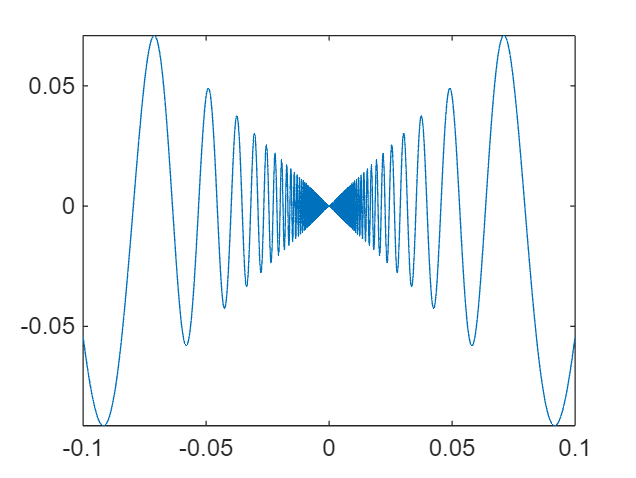

% 题3
Fun = @(x) x.*sin(1/x);
% 使用fplot函数绘制函数图像
fplot(Fun, [-0.1 0.1]);

% 初始化零点数组
zeroPoints = zeros(1,10);
% 使用循环和fzero函数找到函数的零点
for idx=1:10
    zeroPoints(idx)=fzero(Fun,(idx-0.5)*0.01);
end
% 将正负零点合并
zeroPoints=[zeroPoints,-zeroPoints]

zeroPoints =     0.0050    0.0152    0.0245    0.0354    0.0455    0.0531    0.0637    0.0796    0.0796    0.1061   -0.0050   -0.0152   -0.0245   -0.0354   -0.0455   -0.0531   -0.0637   -0.0796   -0.0796   -0.1061


% 题4
Fun = @(x) [9*x(1)^2+36*x(2)^2+4*x(3)^2-36;x(1)^2-2*x(2)^2-20*x(3);16*x(1)-x(1)^3-2*x(2)^2-16*x(3)^2];
% 使用fsolve函数求解非线性方程组
root = fsolve(Fun,[0 0 0]);


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


root =       0.13416      0.99721    -0.098542


disp("求解到的根是")

    "求解到的根是"    "0.13416"    "0.99721"    "-0.098542"



disp(root)

% 题5
fun=@(x)[x(1)-0.7*sin(x(1))-0.2*cos(x(2)),x(2)-0.7*cos(x(1))+0.2*sin(x(2))];
root = fsolve(fun,[0.5 0.5]);


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


root =       0.52652      0.50792


disp("求解到的根是")

求解到的根是


disp(root)

      0.52652      0.50792



% 题6
clear; close;
% 定义t的范围
t=0:pi/100:2*pi;
% 定义x1和y1
x1=2+sqrt(5)*cos(t);
y1=3-2*x1+sqrt(5)*sin(t);
% 定义x2和y2
x2=3+sqrt(2)*cos(t); 
y2=6*sin(t);
% 绘制图像，观察4个解的大致位置，然后分别求解
plot(x1,y1,x2,y2); grid on;
% 定义函数
fun = @(x) [(x(1)-2)^2+(x(2)-3+2*x(1))^2-5,2*(x(1)-3)^2+(x(2)/3)^2-4];
% 使用fsolve函数求解非线性方程组
sol1 = fsolve(fun,[1.5,2])


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


sol1 =     1.6581    1.8936


sol2 = fsolve(fun,[1.8,-2])


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


sol2 =     1.7362   -2.6929


sol3 = fsolve(fun,[3.5,-5])


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


sol3 =     3.4829   -5.6394


sol4 = fsolve(fun,[4,-4])


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


sol4 =     4.0287   -4.1171


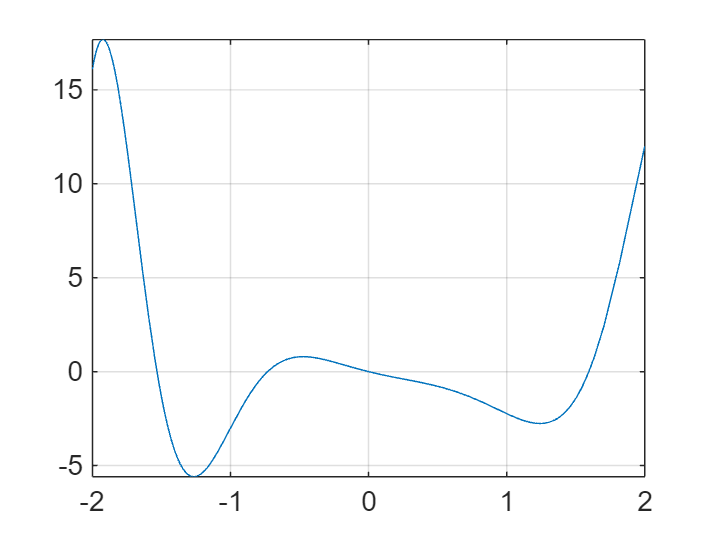

% 题7.1
clear;clc;
% 求坐标的函数
function x1 = findRxtrmum(fun,x0,x0IsMaximum)
    for k =1:length(x0)
        %x1(k)=fzero(dfun,x0(k));continue;  % 导数法
        if x0IsMaximum(k)
            y = @(x) -fun(x);
        else
            y = fun;
        end
        %x1(k)=fminbnd(y,x0(k)-0.3,x0(k)+0.3);  % fminbnd法
        x1(k)=fminsearch(y,x0(k));  % fminsearch法    
    end
end
% 可视化结果的函数
function plotExtremum(fun,x1,interval)
    x1 = sort([x1 interval]); % 将区间的端点添加到极值点中
    y1_values = fun(x1);
    % 将符号表达式转换为数值以进行计算
    [ymin, Imin] = min(y1_values);
    [ymax, Imax] = max(y1_values);
    % 计算原函数在极值点处的值
    figure;
    plot(x1, y1_values, 'k.', 'MarkerSize', 12);
    hold on;
    plot(x1(Imin), ymin, 'ro', 'MarkerSize', 8);
    plot(x1(Imax), ymax, 'bo','MarkerSize', 8);
    fplot(fun, interval,'LineWidth', 1.5);
    title('极值点');xlabel('x'); ylabel('y');
    legend('极值点','最小值点','最大值点','Location','best');
    grid on; hold off;
    %输出结果
    fprintf('极值点 (x):'); disp(x1);
    fprintf('极值 (y):'); disp(y1_values);
    fprintf('最小值点 (x, y):(%.4f, %.4f)\n', x1(Imin), ymin);
    fprintf('最大值点 (x, y):(%.4f, %.4f)\n', x1(Imax), ymax);
end

% 定义函数
syms x
fun = @(x) x.^2.*sin(x.^2-x-2);
interval = [-2 2];
fun_sym = sym(fun);
dfun = matlabFunction(diff(fun_sym, x)); %导函数
fplot(dfun,interval); % 绘制导函数图像
grid on; % 根据图像观察极值点的大致位置

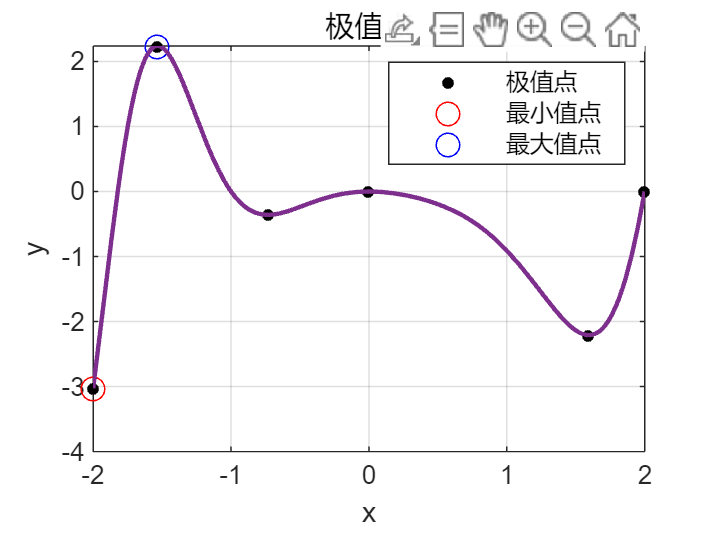

极值点 (x):   -2.0000   -1.5326   -0.7315         0    1.5951    2.0000

极值 (y):   -3.0272    2.2364   -0.3582         0   -2.2080         0

最小值点 (x, y):(-2.0000, -3.0272)
最大值点 (x, y):(-1.5326, 2.2364)


x0 = [-1.5 -0.75 0 1.5];
x0IsMaximum = [1 0 1 0];
x1 = findRxtrmum(fun,x0,x0IsMaximum);
plotExtremum(fun,x1,interval);

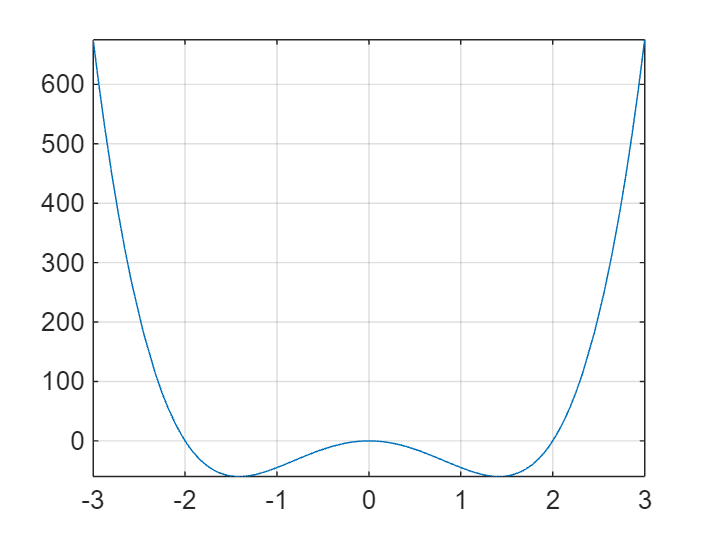

% 题7.2
clear;
syms x
fun = @(x) 3*x.^5-20*x.^3+10;
interval = [-3 3];
fun_sym = sym(fun);
dfun = matlabFunction(diff(fun_sym, x)); %导函数
fplot(dfun,interval); % 绘制导函数图像
grid on; % 根据图像观察极值点的大致位置

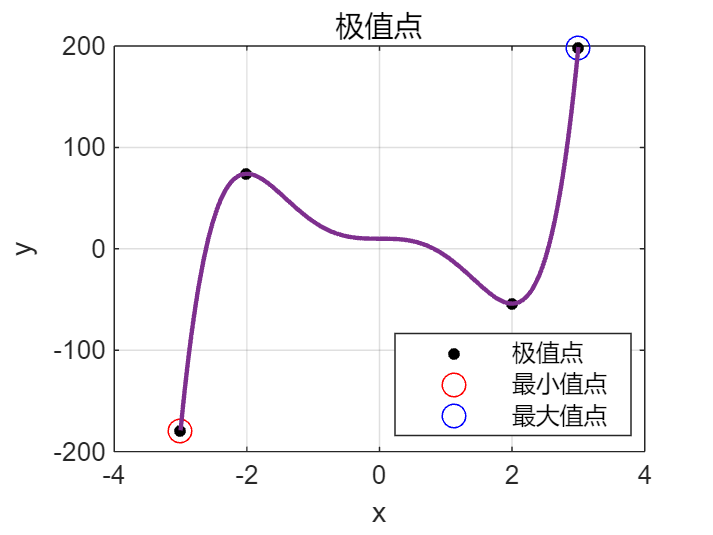

极值点 (x):    -3    -2     2     3

极值 (y):  -179    74   -54   199

最小值点 (x, y):(-3.0000, -179.0000)
最大值点 (x, y):(3.0000, 199.0000)


x0 = [-2 2];
x0IsMaximum = [1 0];
x1 = findRxtrmum(fun,x0,x0IsMaximum);
plotExtremum(fun,x1,interval);

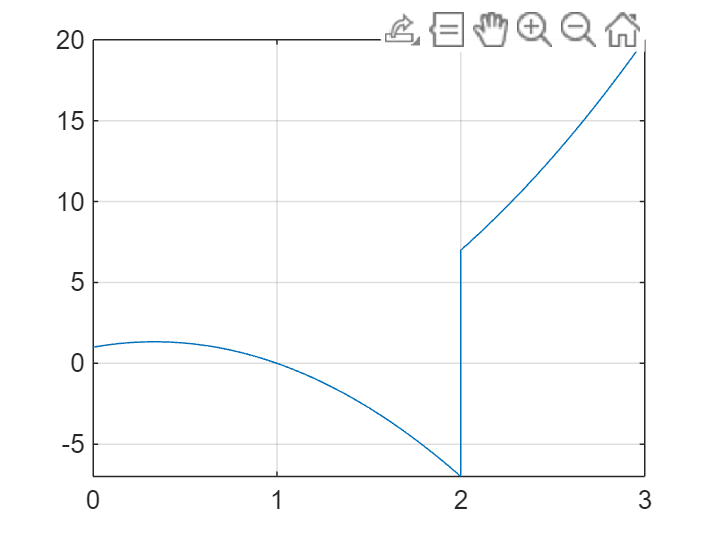

% 题7.3
clear;
syms x
fun = @(x) abs(x.^3-x.^2-x-2);
interval = [0 3];
fun_sym = sym(fun);
dfun = matlabFunction(diff(fun_sym, x)); %导函数
fplot(dfun,interval); % 绘制导函数图像
grid on; % 根据图像观察极值点的大致位置

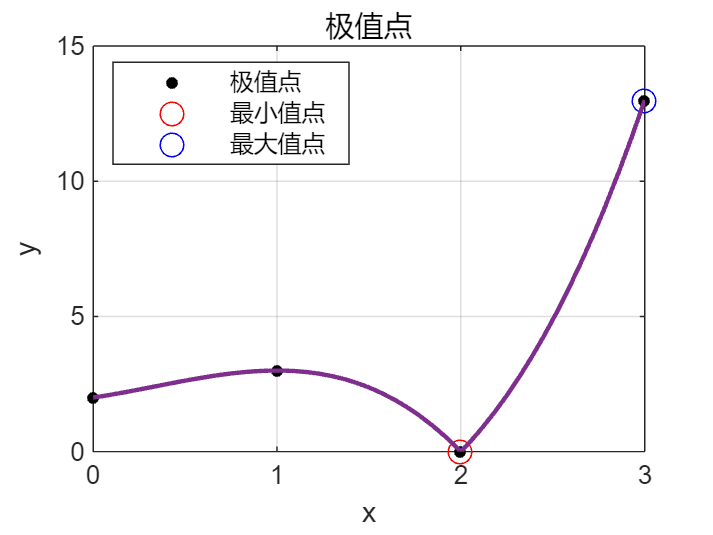

极值点 (x):     0     1     2     3

极值 (y):     2     3     0    13

最小值点 (x, y):(2.0000, 0.0000)
最大值点 (x, y):(3.0000, 13.0000)


x0 = [1 2];
x0IsMaximum = [1 0];
x1 = findRxtrmum(fun,x0,x0IsMaximum);
plotExtremum(fun,x1,interval);

% 题8
rate = 5.04/12/100; % 年利率
period = 20*12; % 贷款期数
totalHousePrice = 7500*180; % 房屋总价格
downPayment = totalHousePrice*0.3; % 首付款额
loanAmount = totalHousePrice - downPayment; % 贷款总额
% 月付还款额
monthlyPayment = (1+rate)^period*rate*loanAmount/((1+rate)^period-1);
fundInterestRate = 4.05/12/100; % 公积金贷款年利率
fundLoan = 60*10000; % 公积金贷款金额
% 公积金贷款的月付还款额
monthlyPayment1 = (1+fundInterestRate)^period*fundInterestRate*fundLoan/((1+fundInterestRate)^period-1);
% 商业贷款金额
commercialLoan = loanAmount - fundLoan;
% 商业贷款的月付还款额
monthlyPayment2 = (1+rate)^period*rate*commercialLoan/((1+rate)^period-1);
% 总的月付还款额
totalMonthlyPayment = monthlyPayment1 + monthlyPayment2;
fprintf("房屋总价格:%4.2f、首付款额:%4.2f、月还款额:%4.2f",totalHousePrice, downPayment, monthlyPayment)

房屋总价格:1350000.00、首付款额:405000.00、月还款额:6257.48

fprintf("如果其中60万元为公积金贷款，月还款额为%4.2f",totalMonthlyPayment)

如果其中60万元为公积金贷款，月还款额为5936.19

% 题9
%根据条件列方程theta*R^2+(pi-2*theta)*r^2-R*r*sin(theta)=pi*r^2/2
%化简得sin(2*theta)-2*theta*cos(2*theta)=pi/2
% 定义函数
fun = @(theta) sin(2*theta) - 2*theta*cos(2*theta) - pi/2;
th = fsolve(fun, pi/4);


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


% 计算R的值
R = 20*cos(th)

R =        11.587


% 题10
% 定义弦截法函数
function root = secantMethod(func, x0, x1, tol)
    while abs(x0-x1) > tol
        root = x1 - (x1-x0)*feval(func, x1)/(feval(func, x1) - feval(func, x0));
        x0 = x1;
        x1 = root;
    end
end

% 定义函数
fun = @(x) x*log(sqrt(x^2-1)+x) - sqrt(x^2-1) - 0.5*x;
% 使用割线法求解
secantMethod(fun, 1, 2, 1e-8)

ans = 2.1155

% 题11
% 定义函数
f = @(x) x.*cos(x) - 2;
function root = dichotomy(f, a, b, tol, n)
    %f: 要求解的函数句柄;a,b: 初始区间,要求f(a)* f(b) <0
    % tol: 误差容限;n: 最大选代次数
    if f(a)* f(b)>= 0
        error('初始区间不满足二分法条件');
    end
    s = 0;
    while abs(b - a) > tol && s < n; c =(a + b) / 2;
        if f(c) == 0; root = c; return;end
        if f(a) * f(c) < 0; b = c; else; a = c; end; s = s + 1;
    end
        if s == n; warning('达到最大迭代次数，可能未找到精确解'); end
    root=(a +b)/2;% 返回区间的中点作为近似解
end

% 使用二分法找到零点
x_solution = dichotomy(f, -4, 2, 1e-6, 1000);

x_solution =       -2.4988


% 打印结果
fprintf('方程的解是%f\n', x_solution);

方程的解是-2.498756


%题12
clear;clc;
% 定义函数和它的导数
f = @(x) x^3 + 4*x^2 - 10;
df = @(x) 3*x^2 + 8*x;

a = 1; b = 2; % 定义区间
tol = 1e-6; % 定义容差
n = 1000; % 最大迭代次数

% 牛顿法
function root = newton(f, df, x, tol, n)
    % f: 要求解的函数句柄, df: 函数f的导数的句柄
    % x: 初始估计值, tol: 误差容限, n: 最大迭代次数
    s = 0;
    while abs(f(x)) > tol && s < n
        x = x - f(x)/df(x);
        s = s + 1;
    end
    if s == n
        warning('达到最大迭代次数，可能未找到精确解');
    end
    root = x; % 返回近似解
end

root = newton(f, df, (a+b)/2, tol, n);
fprintf('牛顿法：%f\n', root);

牛顿法：1.365230


% 二分法
function root = bisection(f, a, b, tol, n)
    %f: 要求解的函数句柄;a,b: 初始区间,要求f(a)* f(b) <0
    % tol: 误差容限;n: 最大选代次数
    if f(a)* f(b)>= 0
        error('初始区间不满足二分法条件');
    end
    s = 0;
    while abs(b - a) > tol && s < n; c =(a + b) / 2;
        if f(c) == 0; root = c; return;end
        if f(a) * f(c) < 0; b = c; else; a = c; end; s = s + 1;
    end
        if s == n; warning('达到最大迭代次数，可能未找到精确解'); end
    root=(a +b)/2;% 返回区间的中点作为近似解
end
root = bisection(f, a, b, tol, n)

root =        1.3652


fprintf('二分法：%f\n', root);

二分法：1.365230
